%% DISEÑO DE UN FILTRO FIR
[x, Fs] = audioread('PDS_P6_3B_LE2_G2.wav');

% A
sound(x, Fs);
Fs

Fs = 96000

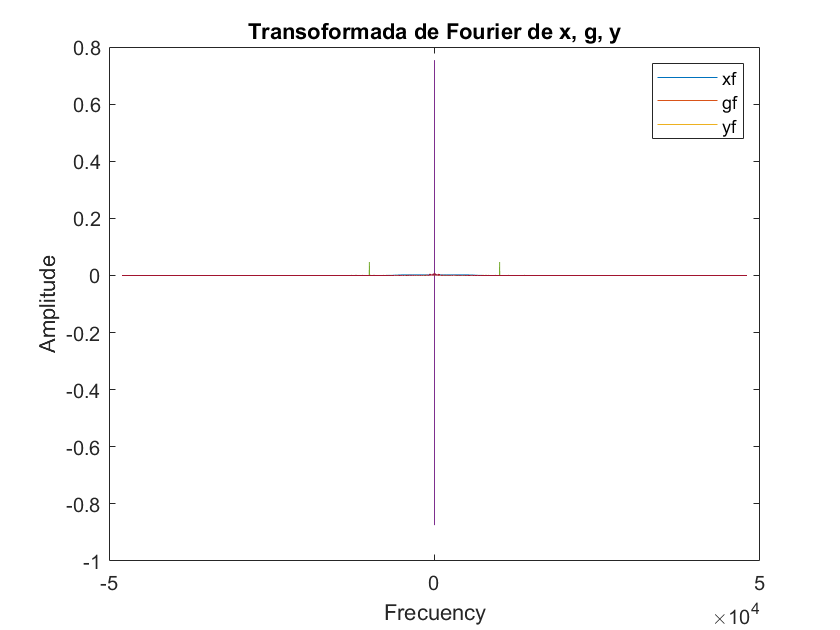

% B 

% La fs del filtro será la misma que la de la señal para que las muestras
% coincidan en el tiempo y se pueda hacer un filtrado adecuado

%Cálculo de la TF de mi señal para ver dónde filtrar

X = fft(x, length(x)) / length(x);
fx = linspace(-Fs/2, Fs/2, length(x));

hold off

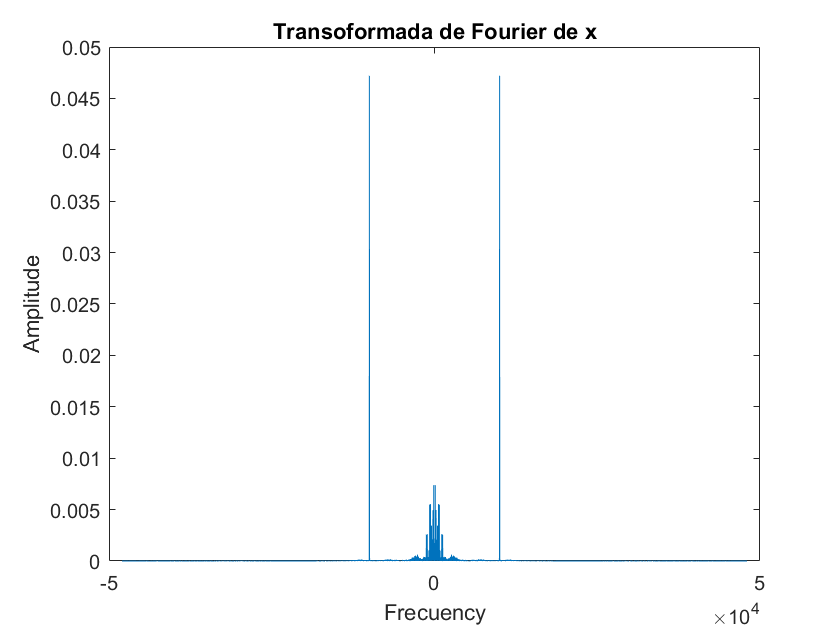

plot(fx, fftshift(abs(X)));
title("Transoformada de Fourier de x")
ylabel("Amplitude")
xlabel("Frecuency")


%La voz humana produce frecuencias de hasta 4KHz si lo que nos interesa es
%mantener una conversación (no música)
%Fc del filtro a 6KHz para dar algo de margen, el pitido está en ~10KHz



%% D
hold off

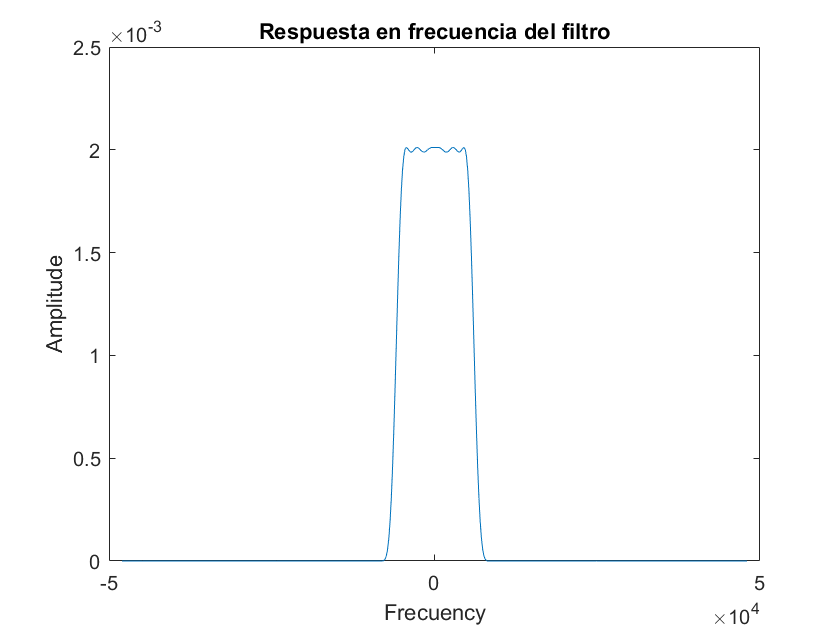

H = fft(h, 500) / 500;
fh = linspace(-Fs/2, Fs/2, length(H));


plot(fh, fftshift(abs(H)));
title("Respuesta en frecuencia del filtro")
ylabel("Amplitude")
xlabel("Frecuency")

hold off

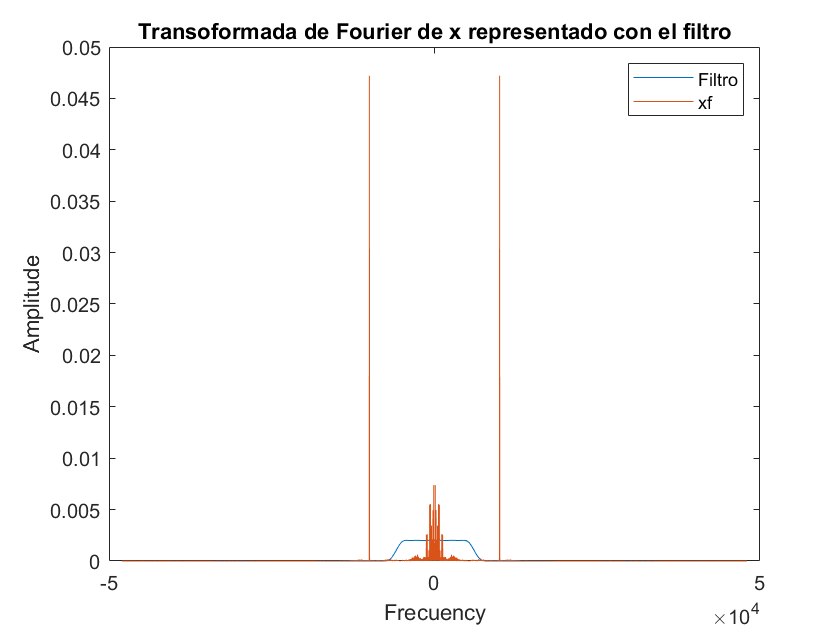

plot(fh, fftshift(abs(H)));
hold on;
plot(fx, fftshift(abs(X)));
legend("Filtro", "xf")
title("Transoformada de Fourier de x representado con el filtro")
ylabel("Amplitude")
xlabel("Frecuency")



%Se ve perfectamente cómo el armónico no deseado (10KHz) se encuentra en la
%banda de atenuación, mientras que la voz (hasta 3-4KHz) queda dentro

%% IMPLEMENTACIÓN DE UN FILTRO FIR UTILIZANDO DFT

L = 500; %Longitud de payload
P = length(h); %P es la longitud del filtro
N = L - P + 1;

%P-1 ceros de primeras
zx = [zeros(1,P-1) x'];

%Transformada del filtro (Matlab (fft) coge por defecto sólo 1 periodo)
H = fft(h, L);

%Salida del filtro, algoritmo
y = [];


for r = 1:floor(length(x)/(L-P+1))

    xr = zx(N*r-N+1:(N*r+P-1));

    Xr = fft(xr, L);
    Yr = Xr.*H;
    yr = ifft(Yr, L);

    y = [y yr(P: end)];

end


sound(y, Fs);


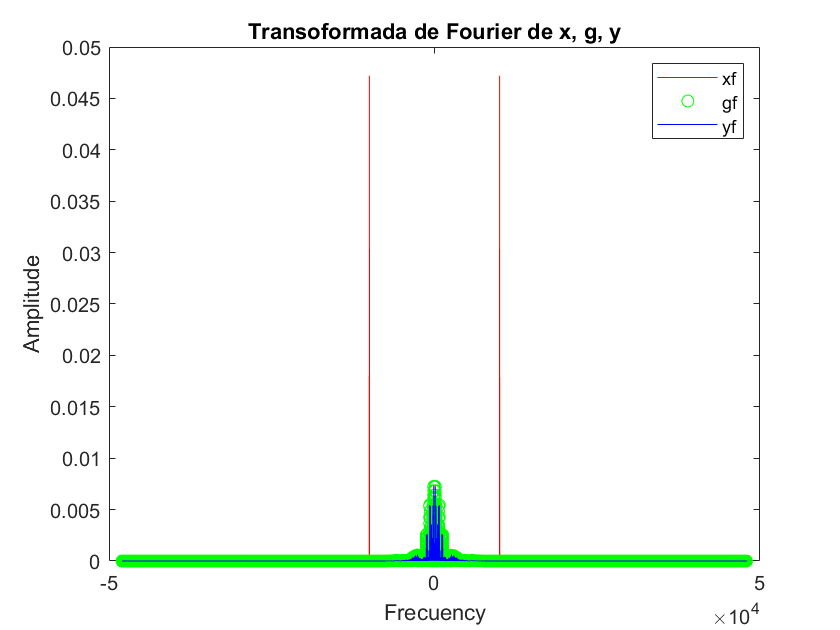

%% ANÁLISIS DE RESULTADOS
% A
g = filter(h, 1, x);
g = g(1:length(y))'; 

%Se eliminan los últimos valores a g (despreciables) para q tenga la misma
%longitud que y, y se dispone en fila.


% B
ty = linspace(0, (1/Fs)*length(y), length(y));
tg = linspace(0, (1/Fs)*length(g), length(g));

hold off

plot(ty, y, "b*");
hold on;
plot(tg, g, "g");
legend("y", "g")
title("Señales y, g")
ylabel("Amplitude")
xlabel("Time")

%Se ve perfectamente que son idénticas


% C
ECM = (1/length(g))*sum((g - y).^2)

ECM = 2.1201e-33

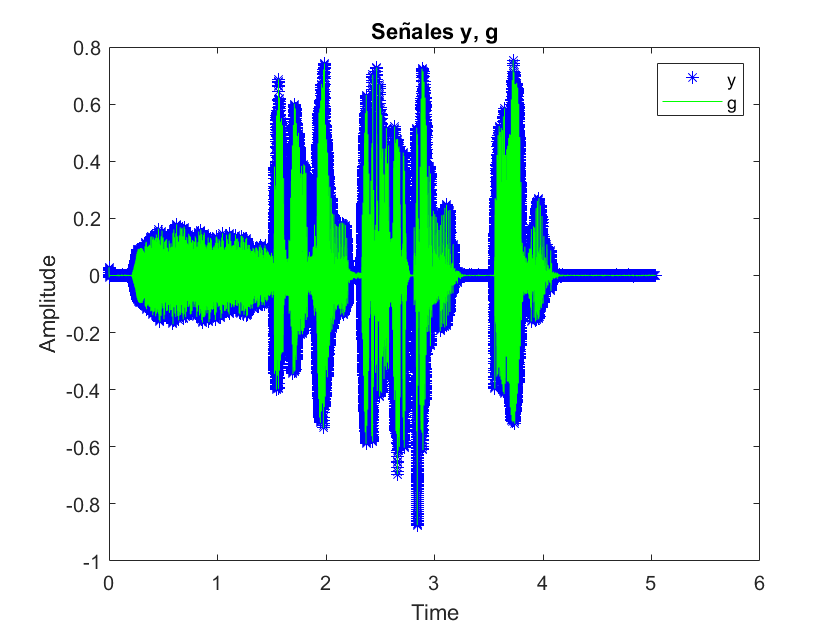

% ~0, como era de esperar


% D
G = fft(g, length(g)) / length(g);
fg = linspace(-Fs/2, Fs/2, length(G));


Y = fft(y, length(y)) / length(y);
fy = linspace(-Fs/2, Fs/2, length(Y));

hold off

plot(fx, fftshift(abs(X)), "r");
hold on;
plot(fg, fftshift(abs(G)), "go");
plot(fy, fftshift(abs(Y)), "b");
legend("xf", "gf", "yf")
title("Transoformada de Fourier de x, g, y")
ylabel("Amplitude")
xlabel("Frecuency")





%DEBUG
%disp(i);
%disp(N*i-N+1);
%disp(N*i+P-1);
%disp(" ");


